clear
clf

data = readmatrix('rpalus_data_02222023.csv');
num_datapoints = (length(data));
addpath ../ % for access to fit_data function

% label data from csv
time = data(:, 1) / 60;     % hours
old_10percent = data(:, 2); % optical density
old_40percent = data(:, 3); % optical density
old_50percent = data(:, 4); % optical density
old_60percent = data(:, 5); % optical density
new_10percent = data(:, 6); % optical density
nfm_medium = data(:, 7); % optical density

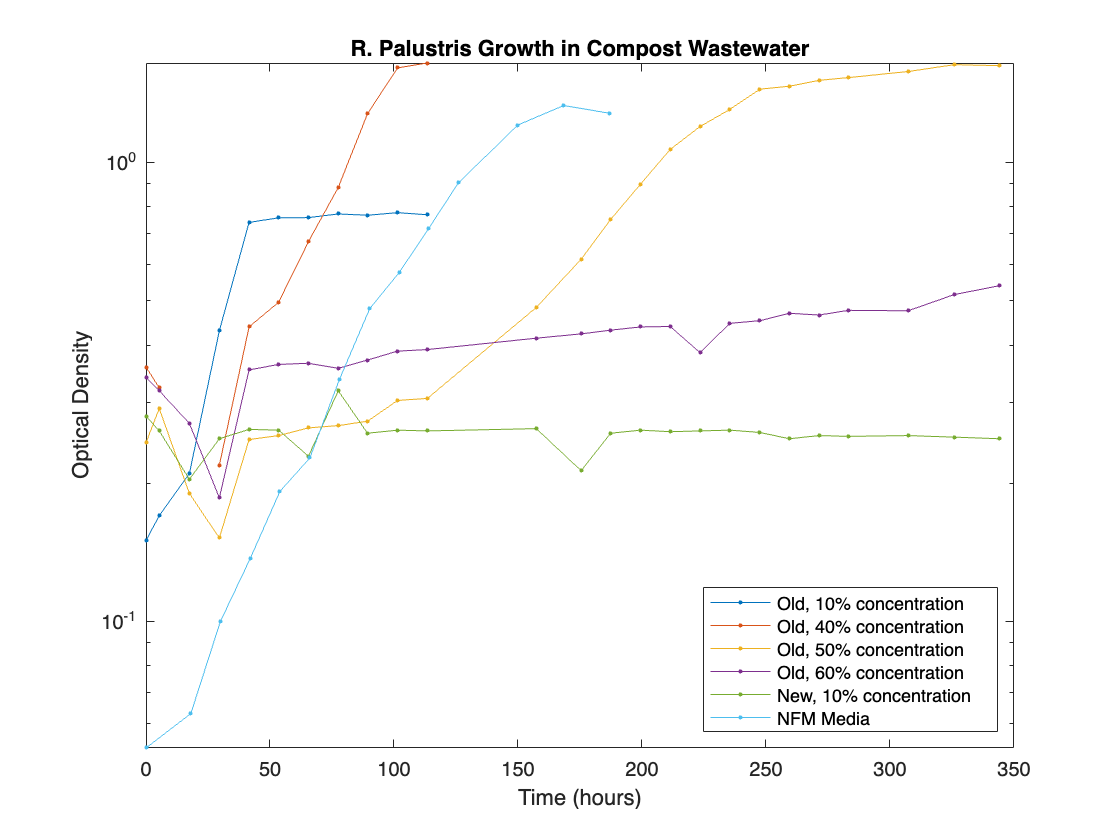

figure
semilogy(time, old_10percent, '.-');
hold on
semilogy(time, old_40percent, '.-');
semilogy(time, old_50percent, '.-');
semilogy(time, old_60percent, '.-');
semilogy(time, new_10percent, '.-');
semilogy(time - 9442/60, nfm_medium, '.-'); % normalize time @ zero

nfm_medium = data(:, 7); % optical density
title("R. Palustris Growth in Compost Wastewater")
xlabel("Time (hours)")
ylabel("Optical Density")
legend("Old, 10% concentration", "Old, 40% concentration", "Old, 50% concentration", ...
       "Old, 60% concentration", "New, 10% concentration", "NFM Media",...
       'location', 'southeast')
hold off

### Phase 1

Phase 1 occurred between 2/15 and 2/20. Data was taken approximately every 12 hours for the following:

- Old, 10% concentration

- Old, 40% concentration

- Old, 50% concentration

- Old, 60% concentration

- New, 10% concentration

Significant growth occured for old 10% and old 40% (see analysis section). The remaining mediums continued to be monitored for growth in phase 2.

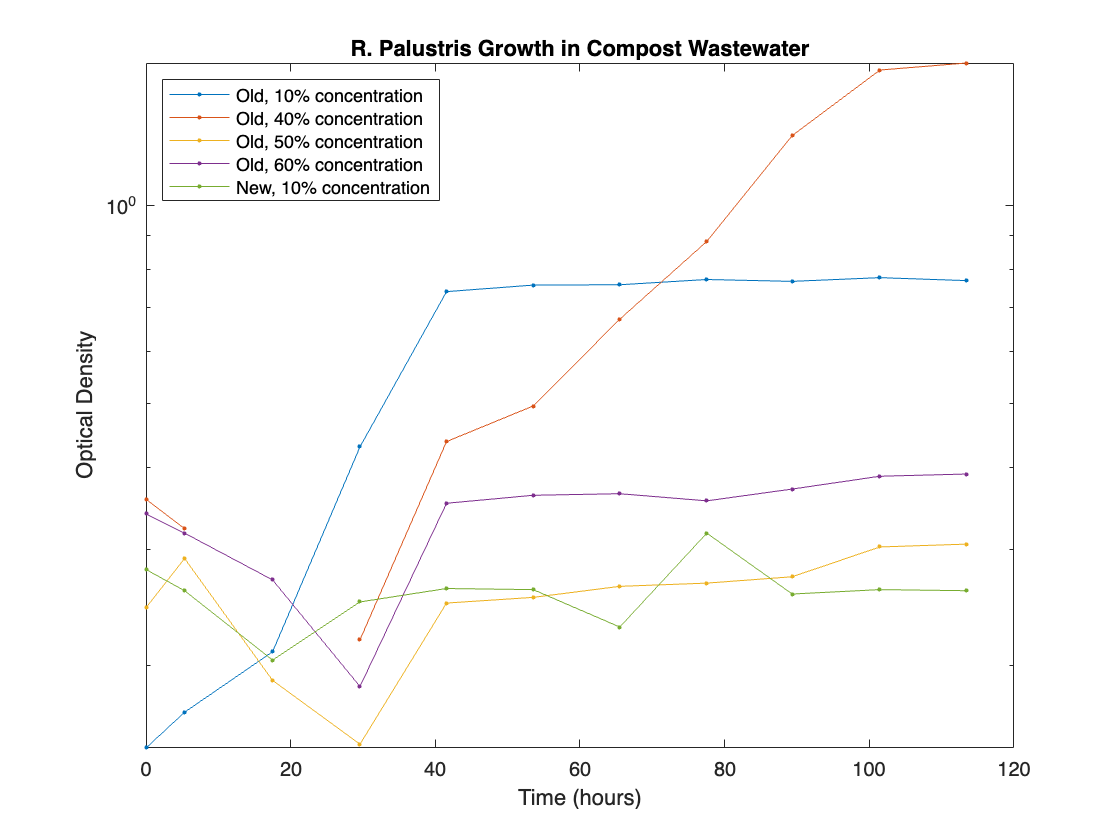

% limit time to phase 1
phase1_split = 1:11;

% Plot
figure
semilogy(time(phase1_split), old_10percent(phase1_split), '.-');
hold on
semilogy(time(phase1_split), old_40percent(phase1_split), '.-');
semilogy(time(phase1_split), old_50percent(phase1_split), '.-');
semilogy(time(phase1_split), old_60percent(phase1_split), '.-');
semilogy(time(phase1_split), new_10percent(phase1_split), '.-');
title("R. Palustris Growth in Compost Wastewater")
xlabel("Time (hours)")
ylabel("Optical Density")
legend("Old, 10% concentration", "Old, 40% concentration", "Old, 50% concentration", ...
       "Old, 60% concentration", "New, 10% concentration", 'location', 'northwest')
hold off

### Phase 2 Data

Phase 2 occurred between 2/22 and 2/27. Data was taken approximately every 12 hours for the following:

- Old, 50% concentration

- Old, 60% concentration

- New, 10% concentration

- NFM medium

### Compost Wastewater Medium

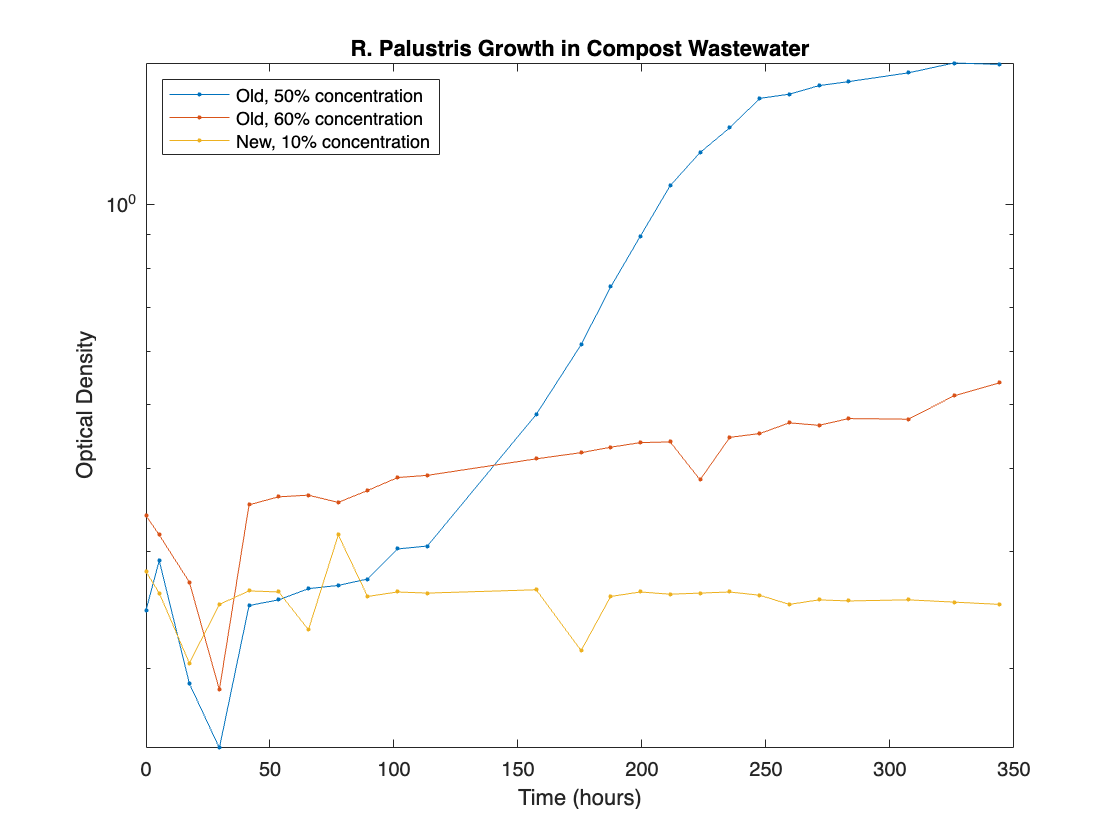

% Plot
figure(2)
semilogy(time, old_50percent, '.-');
hold on
semilogy(time, old_60percent, '.-');
semilogy(time, new_10percent, '.-');
title("R. Palustris Growth in Compost Wastewater")
xlabel("Time (hours)")
ylabel("Optical Density")
legend("Old, 50% concentration", "Old, 60% concentration", "New, 10% concentration", ...
       'location', 'northwest')
hold off

### NFM Medium

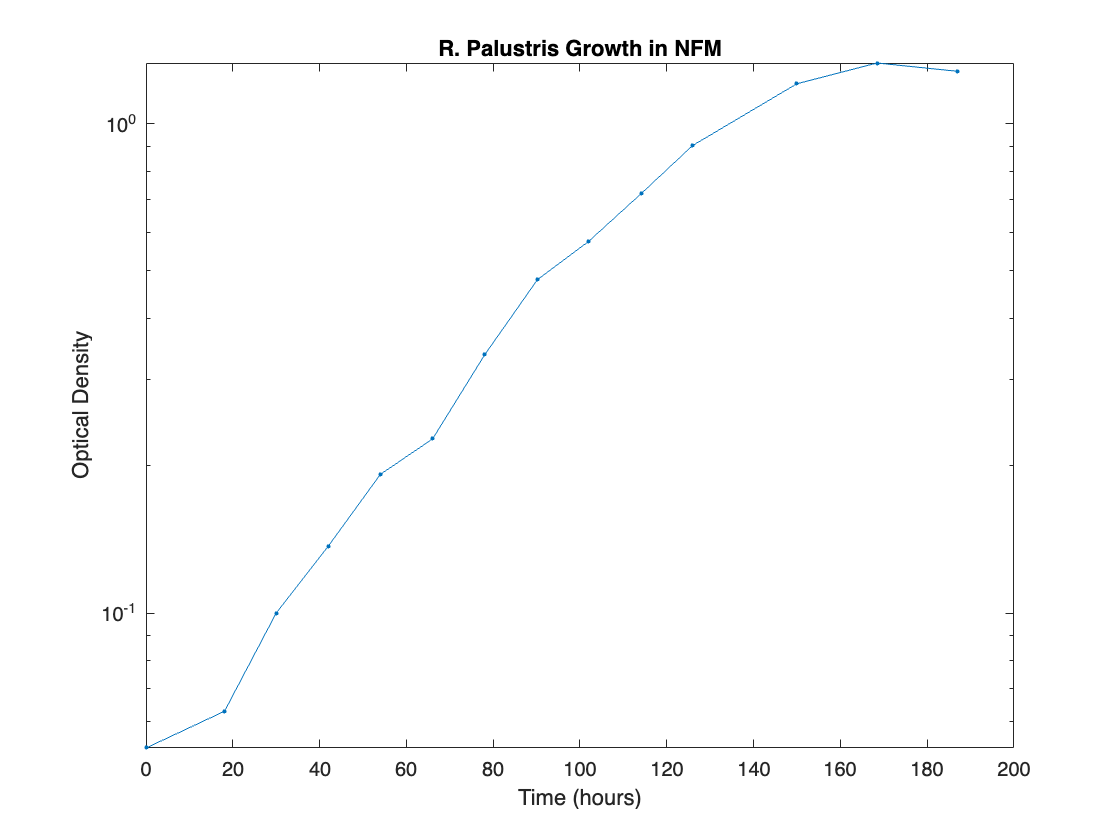

phase2_split = 12:num_datapoints;
figure(3)
semilogy(time(phase2_split) - (9442/60), nfm_medium(phase2_split), '.-');
title("R. Palustris Growth in NFM")
xlabel("Time (hours)")
ylabel("Optical Density")

## Fitting & Analysis

### Old, 10%

We isolated the exponential section of the 40% curve, which happens between the 3rd and 5th data point.

figure
isolate_10 = 3:5;

We can now use the `fit` function to get an exponential fit.

[fitobject_old10,gof_old10] = fit_data(old_10percent, isolate_10, time)

fitobject_old10 =      General model Exp1:
     fitobject_old10(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =     0.09516  (-0.08572, 0.276)
       b =     0.04953  (-0.0004514, 0.09951)

gof_old10 = struct with fields:
           sse: 6.2228e-04
       rsquare: 0.9956
           dfe: 1
    adjrsquare: 0.9912
          rmse: 0.0249


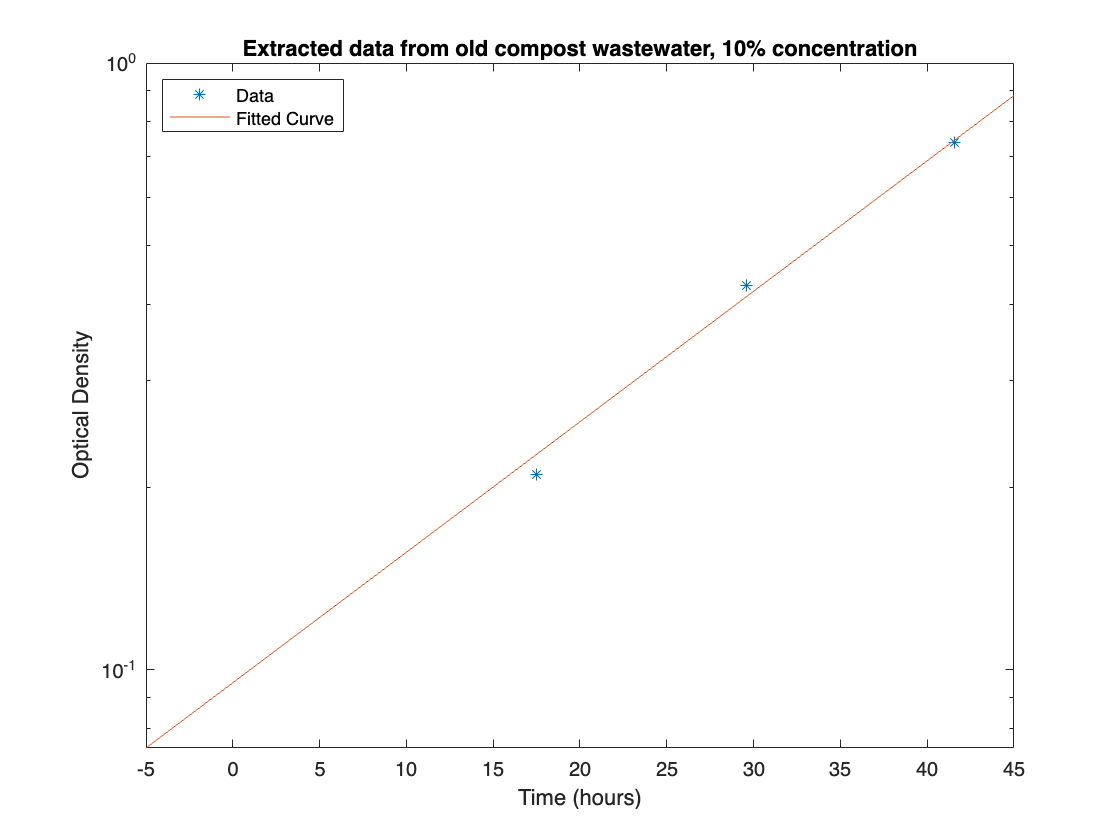

title('Extracted data from old compost wastewater, 10% concentration')

The `fit` function outputs an exponential fit of:


$$f\left(x\right)=0\ldotp 09516*e^{0\ldotp 04953x}$$


with an r squared value is 0.9956. We can plot this fit over the original data.

### Old, 40%

We isolated the exponential section of the 40% curve, which happens between the 4th and 10th data point.

figure
isolate_40 = 4:10;

We can now use the `fit` function to get an exponential fit.

[fitobject40,gof40] = fit_data(old_40percent, isolate_40, time)

fitobject40 =      General model Exp1:
     fitobject40(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =      0.1368  (0.0975, 0.176)
       b =     0.02445  (0.02124, 0.02766)

gof40 = struct with fields:
           sse: 0.0132
       rsquare: 0.9910
           dfe: 5
    adjrsquare: 0.9892
          rmse: 0.0514


The `fit` function outputs an exponential fit of:


$$f\left(x\right)=0\ldotp 1368*e^{0\ldotp 02445x}$$


with an r squared value is 0.9910. We can plot this fit over the original data.

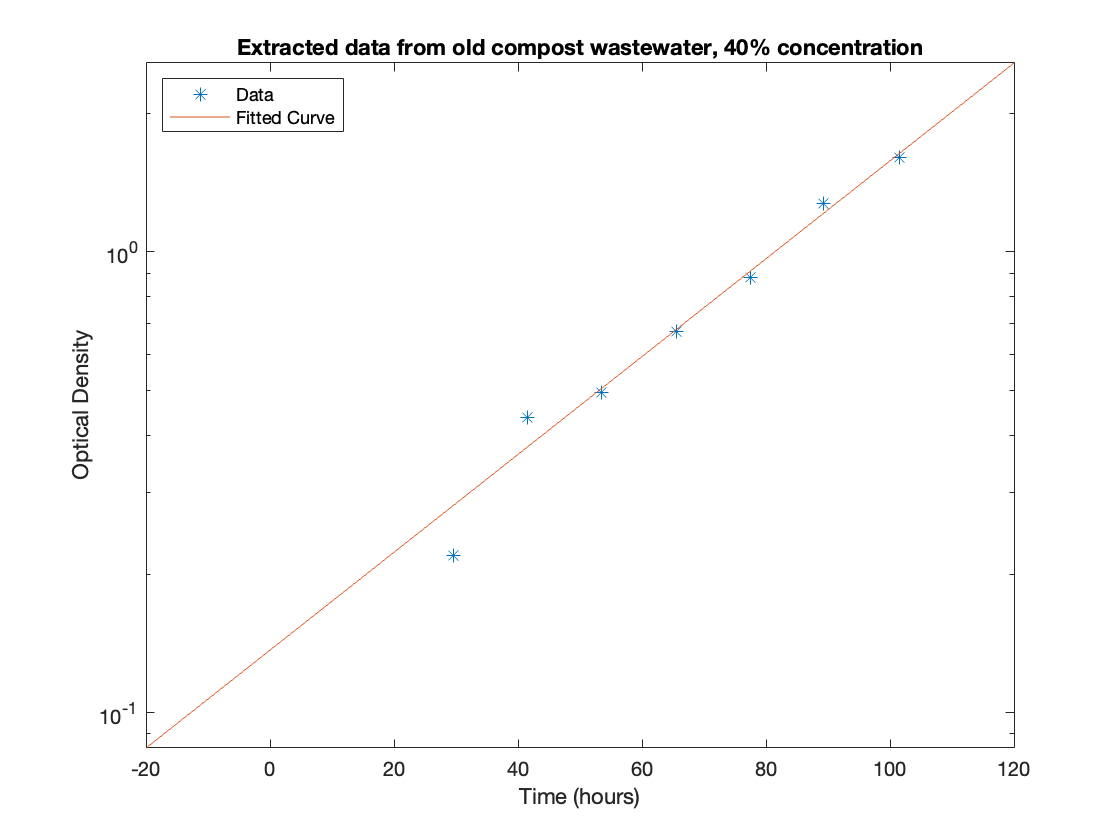

title('Extracted data from old compost wastewater, 40% concentration')

### Old, 50%

We isolated the exponential section of the 50% curve, which happens between the 4th and 10th data point.

figure
isolate_50 = 11:16;

We can now use the `fit` function to get an exponential fit.

[fitobject50,gof50] = fit_data(old_50percent, isolate_50, time)

fitobject50 =      General model Exp1:
     fitobject50(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =     0.05536  (0.03566, 0.07507)
       b =     0.01394  (0.01211, 0.01578)

gof50 = struct with fields:
           sse: 0.0023
       rsquare: 0.9940
           dfe: 4
    adjrsquare: 0.9925
          rmse: 0.0240


The `fit` function outputs an exponential fit of:


$$f\left(x\right)=0\ldotp 05536*e^{0\ldotp 01394x}$$


with an r squared value is 0.9940. We can plot this fit over the original data.

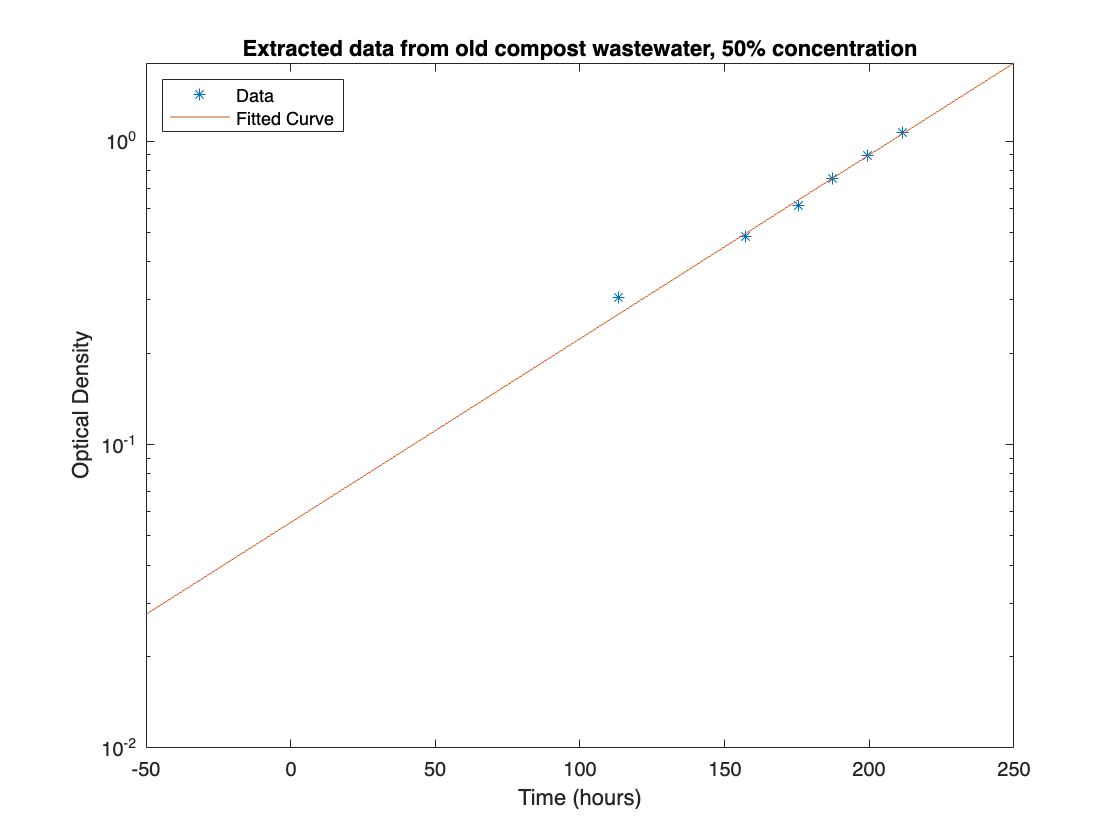

title('Extracted data from old compost wastewater, 50% concentration')

### NFM Media

We isolated the exponential section of the 40% curve, which happens between the 4th and 10th data point.

figure
isolate_nfm = 12:21;

We can now use the `fit` function to get an exponential fit.

[fitobject_nfm,gof_nfm] = fit_data(nfm_medium, isolate_nfm, time)

fitobject_nfm =      General model Exp1:
     fitobject_nfm(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =    0.001586  (0.0006613, 0.002511)
       b =     0.02266  (0.02038, 0.02493)

gof_nfm = struct with fields:
           sse: 0.0042
       rsquare: 0.9914
           dfe: 8
    adjrsquare: 0.9903
          rmse: 0.0228


The `fit` function outputs an exponential fit of:


$$f\left(x\right)=0\ldotp 001586*e^{0\ldotp 02266x}$$


with an r squared value is 0.9914. We can plot this fit over the original data.

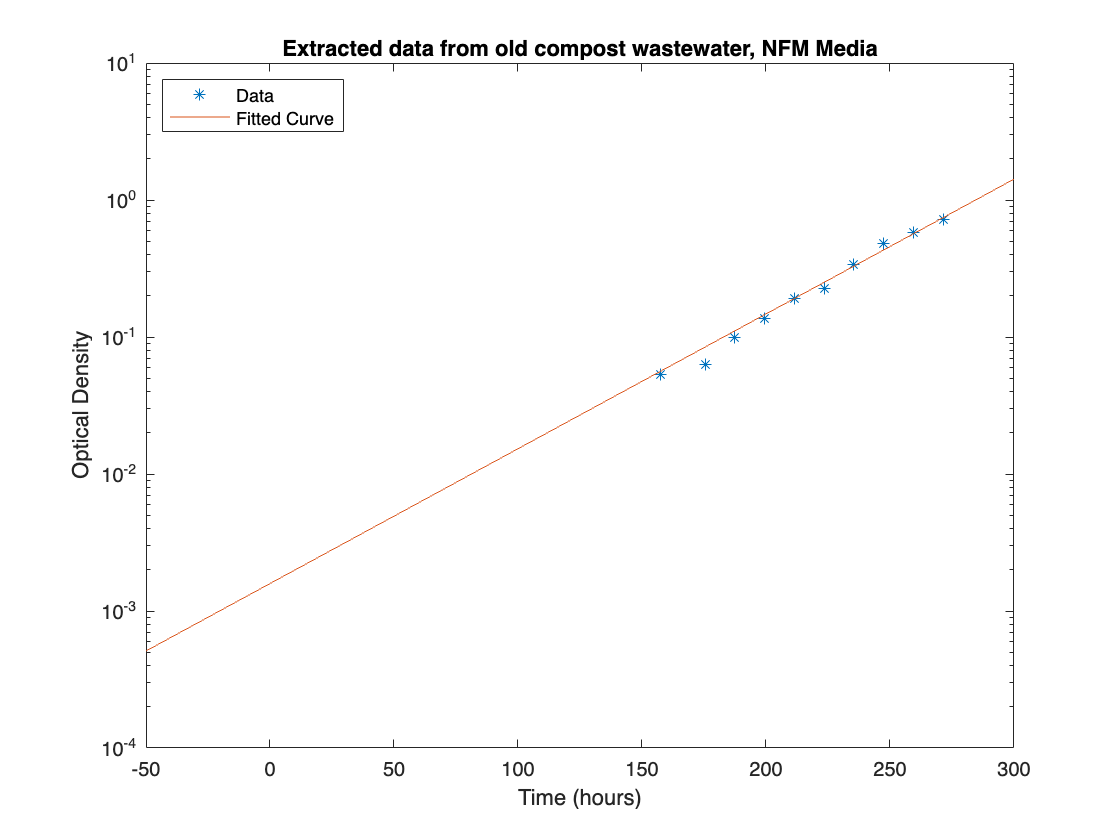

title('Extracted data from old compost wastewater, NFM Media')